# Example 6.29: Detection of Water Contaminants (1 mM SDS)

Note: this script reproduces Example 6.29 (Section 6.7.2) of **Statistics for Chemical Engineers**: a CNN that detects SDS in water from micrographs of liquid-crystal droplets. Shiyi (Amy) Qin and Victor Z UW-Madison, 2024 use CNN for classifying LC droplet micrographs: no SDS vs 1 mM SDS (case I)

clc; clear all; close all hidden;

% load data: X is 256 x 256 x 3 x 100 (color micrographs), y is the label (0 = no SDS, 1 = SDS)
load('Data/lc_sds_caseI.mat')
X = double(X)/255;                 % scale pixel values to [0,1]
Y = categorical(y, [0 1], {'no SDS', '1 mM SDS'});

% split data: 80 images for training and 20 for validation (same proportion of each class)
rng(0);
cv = cvpartition(Y, 'HoldOut', 0.2);
XTrain = X(:,:,:,training(cv)); YTrain = Y(training(cv));
XValidation = X(:,:,:,test(cv)); YValidation = Y(test(cv));

% define CNN architecture: one convolutional layer with 1 3x3 filter(s) and ReLU activation
layers = [
    imageInputLayer([256 256 3], 'Normalization', 'none')  % height, width, and channel size

    convolution2dLayer(3, 1, 'Padding', 'same')
    reluLayer

    fullyConnectedLayer(2)          % fully connected layer has 2 classes
    softmaxLayer
    classificationLayer
    ];

## Training

train CNN

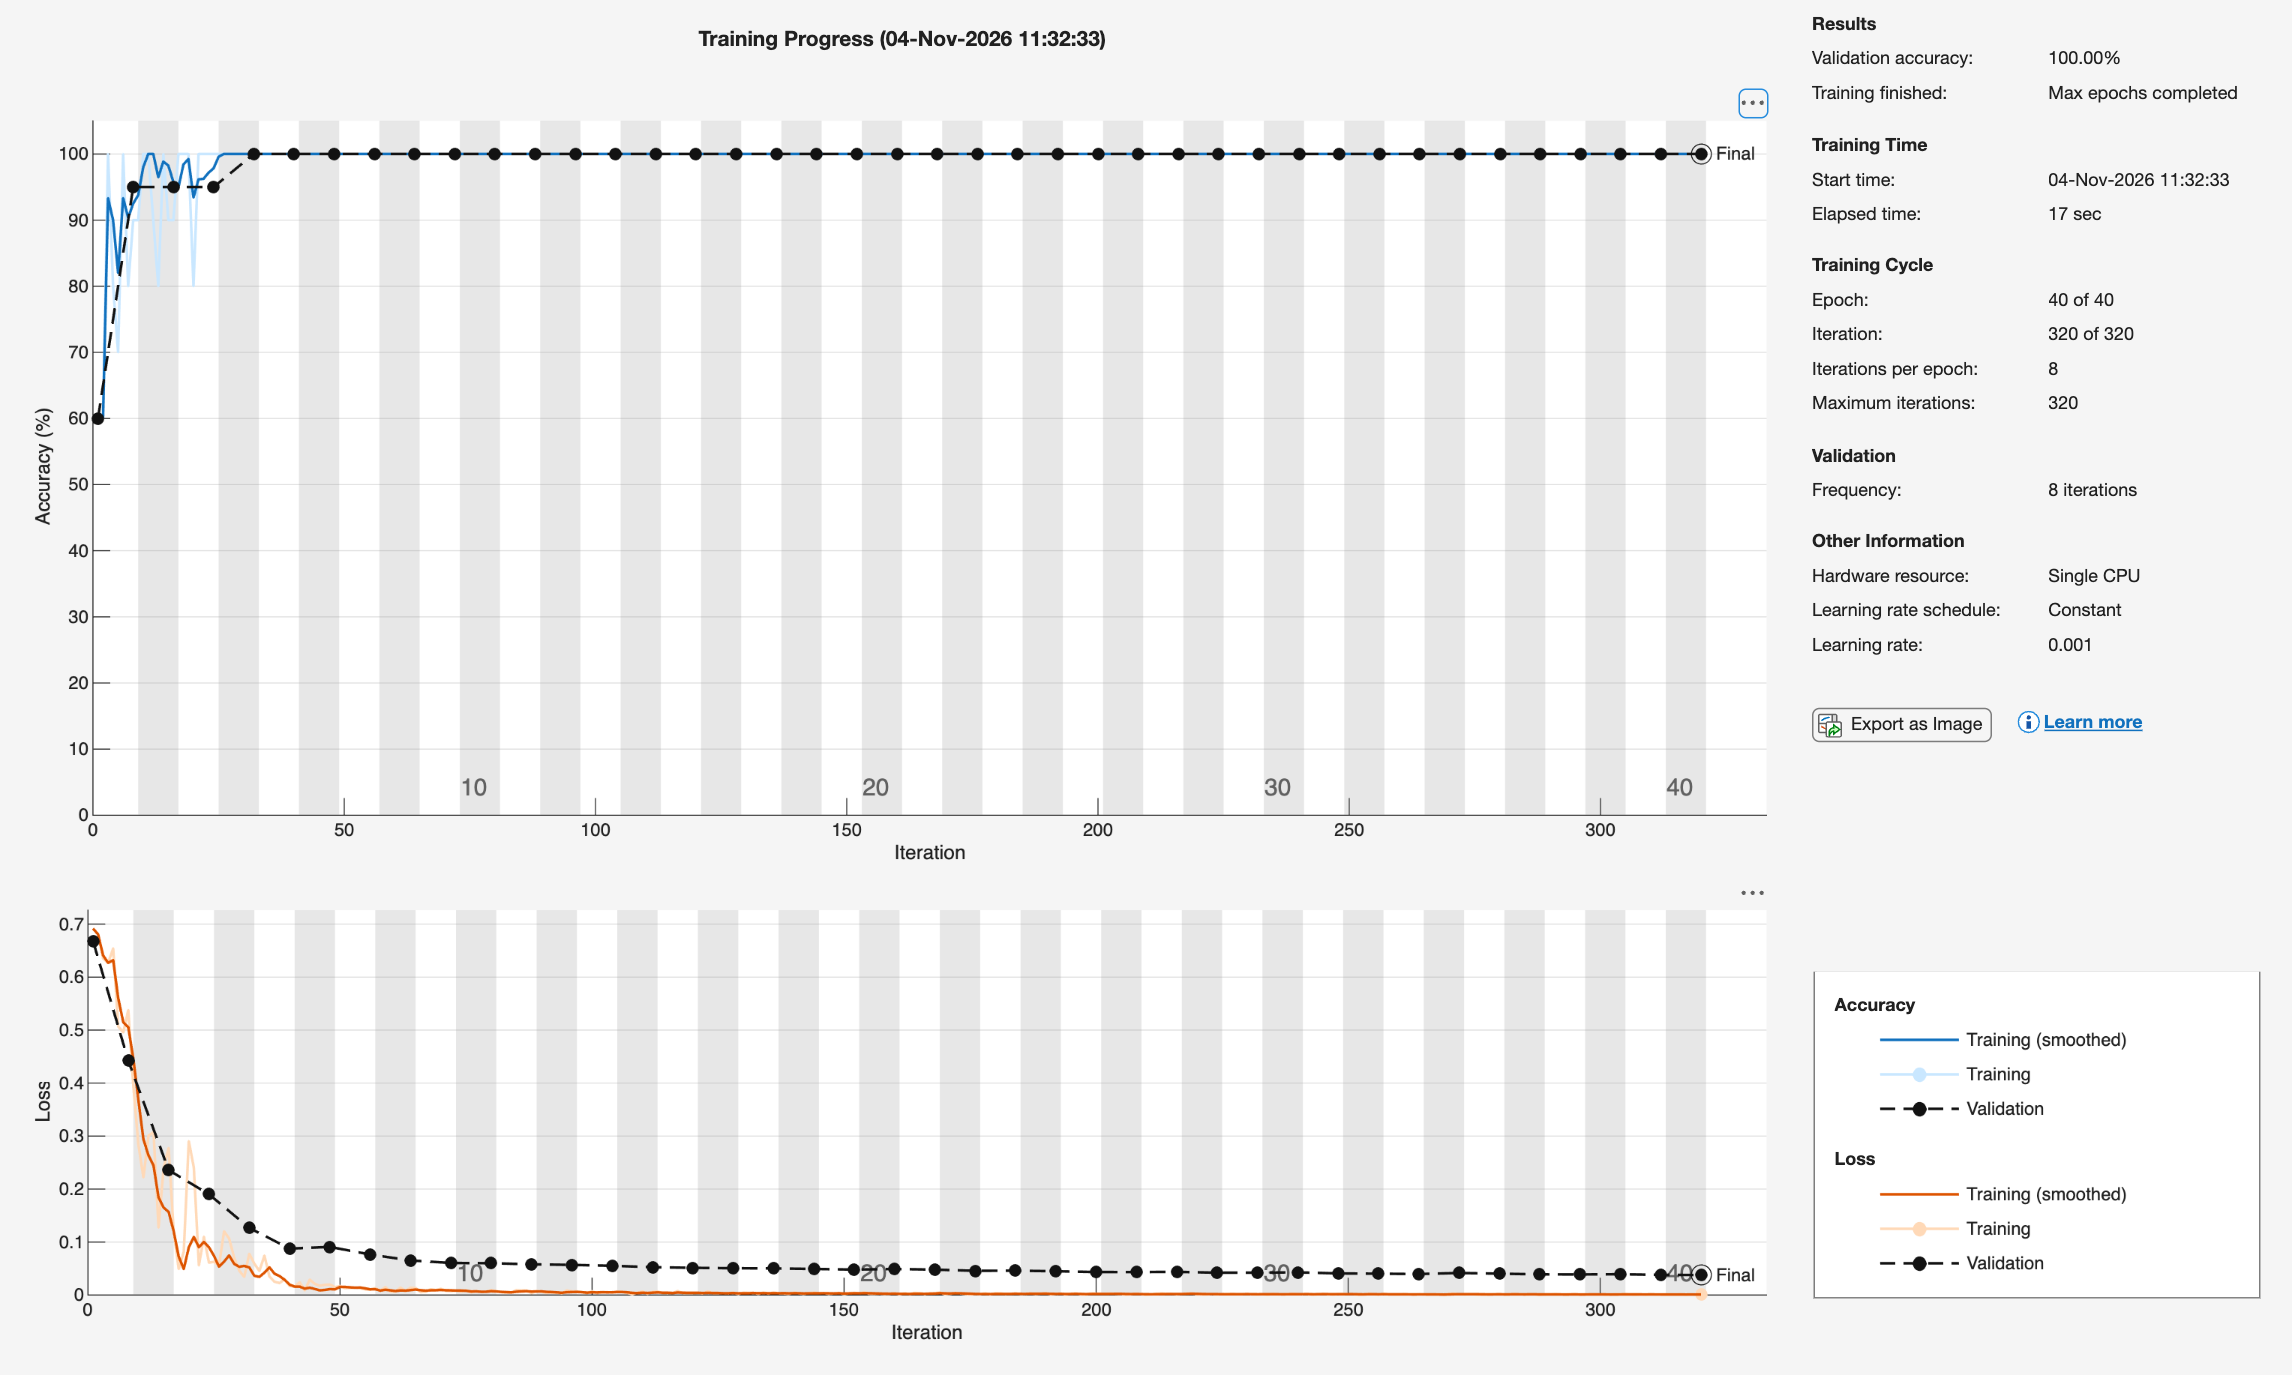

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs', 40, ...
    'MiniBatchSize', 10, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', {XValidation, YValidation}, ...
    'ValidationFrequency', 8, ...
    'Verbose', false, ...
    'Plots', 'training-progress');

net = trainNetwork(XTrain, YTrain, layers, options);

## Accuracy

obtain training accuracy

YPredT = classify(net, XTrain);
accuracyTrain = sum(YPredT == YTrain)/numel(YTrain)

accuracyTrain = 1


% obtain validation accuracy
YPredV = classify(net, XValidation);
accuracyValidation = sum(YPredV == YValidation)/numel(YValidation)

accuracyValidation = 1

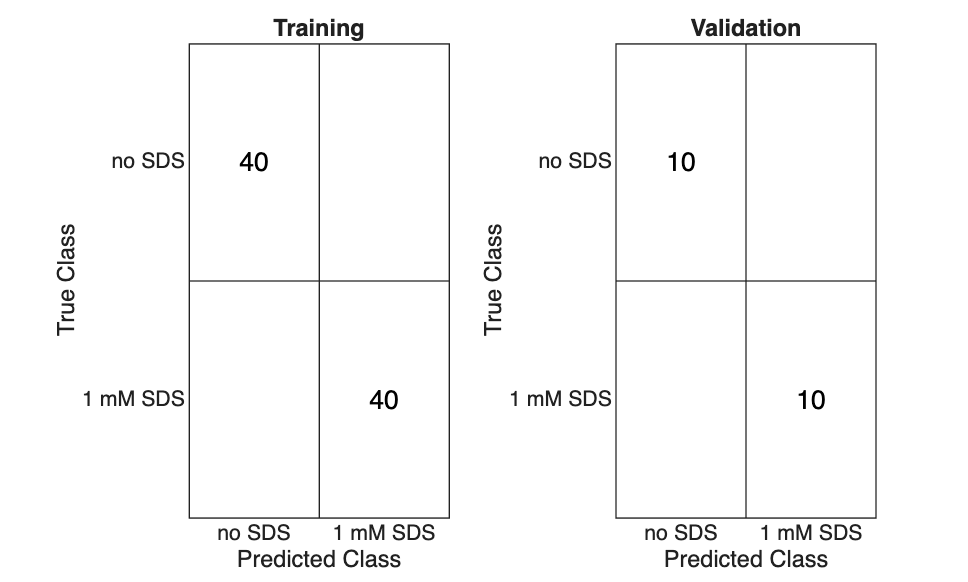


% confusion matrices
figure(2)
subplot(1,2,1)
confusionchart(YTrain, YPredT, 'DiagonalColor', [1 1 1], 'OffDiagonalColor', [0 0 0]);
title('Training')
subplot(1,2,2)
confusionchart(YValidation, YPredV, 'DiagonalColor', [1 1 1], 'OffDiagonalColor', [0 0 0]);
title('Validation')
print -depsc ch6_lcdroplet_sds_confusion_caseI.eps


% display filters
net.Layers(2).Weights

ans = 3×3×3 single array
ans(:,:,1) =
   -0.2781    0.0294   -0.1808
    0.2404   -0.2649    0.1438
   -0.1501    0.0963    0.1747
ans(:,:,2) =
    0.2073   -0.2092    0.2822
   -0.0364    0.3485    0.0494
   -0.3384   -0.2745    0.4212
ans(:,:,3) =
   -0.3427    0.3886    0.2755
   -0.0507   -0.4012    0.3143
   -0.3274    0.2239   -0.3319

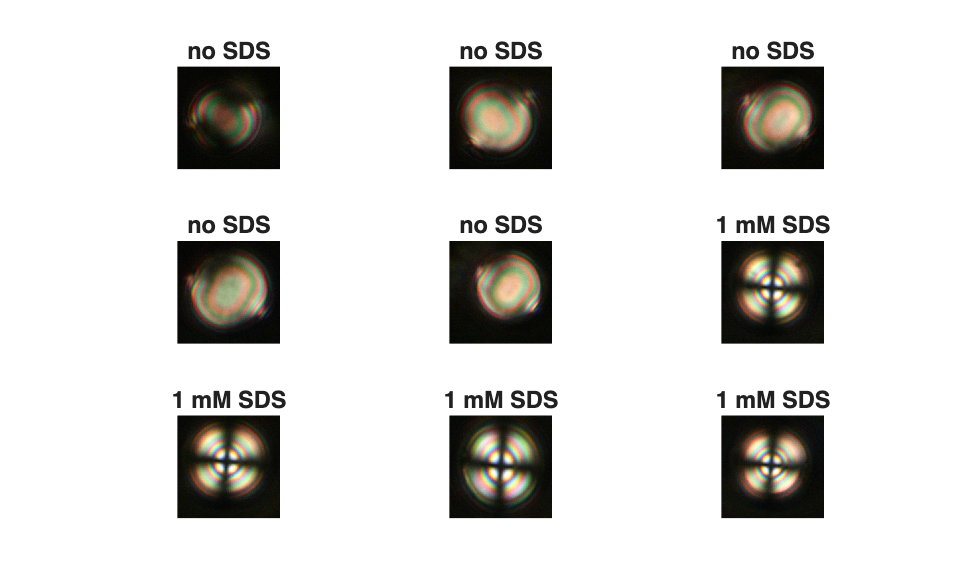


% display some of the images in the validation set (both classes)
cats = categories(Y);
idx = [find(YValidation == cats{1}, 5); find(YValidation == cats{2}, 4)];
figure(1)
for i = 1:9
    subplot(3,3,i);
    imshow(XValidation(:,:,:,idx(i)));
    title(char(YValidation(idx(i))))
end
print -depsc ch6_lcdroplet_sds_data_caseI.eps

## Activations

get activations of the convolutional layer (first filter)

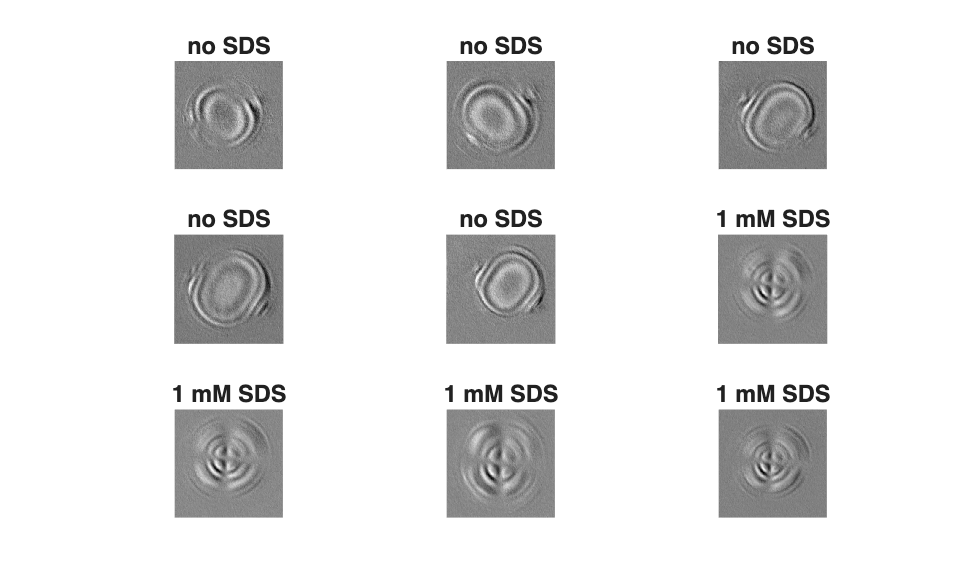

Act = activations(net, XValidation, 2);

figure(3)
for i = 1:9
    subplot(3,3,i)
    imshow(rescale(Act(:,:,1,idx(i))))
    title(char(YValidation(idx(i))))
end
print -depsc ch6_lcdroplet_sds_activations_caseI.eps

## Note

As in the book, the CNN classifies the droplets perfectly (100% validation accuracy): the spatial pattern of the droplets encodes the presence of SDS.